# Credit Scorecard Development

## Scope

% añado comentario
ModelName = 'Refaat 2011 Credit Card Model';
ModelVersion = '1.0';
ModelStatus = 'Draft';
Title = 'Refaat 2011 Credit Card Model';
Subject = 'Model Development Documentation';

Load dataset from Refaat 2011

whos -file CreditCardData

  Name             Size            Bytes  Class    Attributes

  data              -              84876  table              
  dataMissing       -              84876  table              
  dataWeights       -              94720  table              



load CreditCardData.mat

Standardize variable names

data.Properties.VariableNames{'CustID'} = 'IDVar';
data.Properties.VariableNames{'status'} = 'ResponseVar';
dataMissing.Properties.VariableNames{'CustID'} = 'IDVar';
dataMissing.Properties.VariableNames{'status'} = 'ResponseVar';
dataWeights.Properties.VariableNames{'CustID'} = 'IDVar';
dataWeights.Properties.VariableNames{'status'} = 'ResponseVar';
dataWeights.Properties.VariableNames{'RowWeights'} = 'WeightsVar';

filteredData = dataMissing;
filteredData(:,'CustAge') = [];% Sensitive attribute

summary(dataMissing(:,'CustAge'))


Description:  Credit card dataset, from: M. Refaat, Credit Risk Scorecards, lulu.com, 2011.

Variables:

    CustAge: 1200×1 double

        Values:

            Min              21    
            Median           45    
            Max              74    
            NumMissing       30    



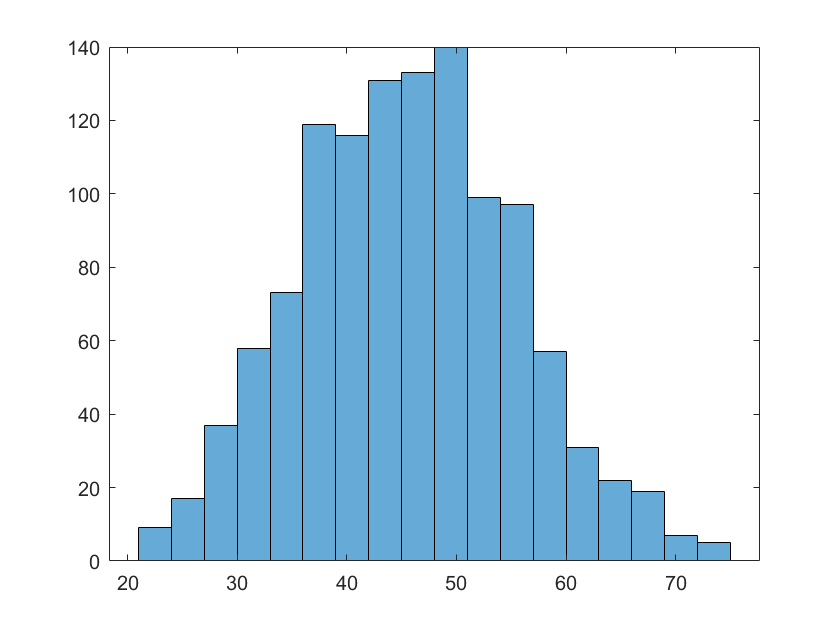

histogram(dataMissing{:,'CustAge'})

Set the response variable to the status column

responseVar = "ResponseVar";

Remove the ID variable from the list of predictors

idVar = "IDVar";

Create a separate bin for missing data values

binMissingData = true;

Use observation weights if they are present

weightsVar = "WeightsVar";
if ~ismember( weightsVar, filteredData.Properties.VariableNames )
    weightsVar = '';
end

Create the credit scorecard object

sc = creditscorecard(filteredData,...
    'IDVar',idVar,...
    'ResponseVar',responseVar,...
    'BinMissingData',binMissingData,...
    'WeightsVar',weightsVar);
disp(sc)

  creditscorecard with properties:

                GoodLabel: 0
              ResponseVar: 'ResponseVar'
               WeightsVar: ''
                 VarNames: {1×10 cell}
        NumericPredictors: {1×5 cell}
    CategoricalPredictors: {1×3 cell}
           BinMissingData: 1
                    IDVar: 'IDVar'
            PredictorVars: {1×8 cell}
                     Data: [1200×10 table]



sc_binned = autobinning(sc,'PredictorVar',{'TmAtAddress'});

bi = bininfo(sc_binned,'TmAtAddress')

bi = 4×6 table
         Bin         Good    Bad     Odds        WOE       InfoValue 
    _____________    ____    ___    ______    _________    __________

    {'[-Inf,23)'}    239     129    1.8527    -0.087767     0.0023963
    {'[23,83)'  }    480     232     2.069      0.02263    0.00030269
    {'[83,Inf]' }     84      36    2.3333      0.14288       0.00199
    {'Totals'   }    803     397    2.0227          NaN      0.004689


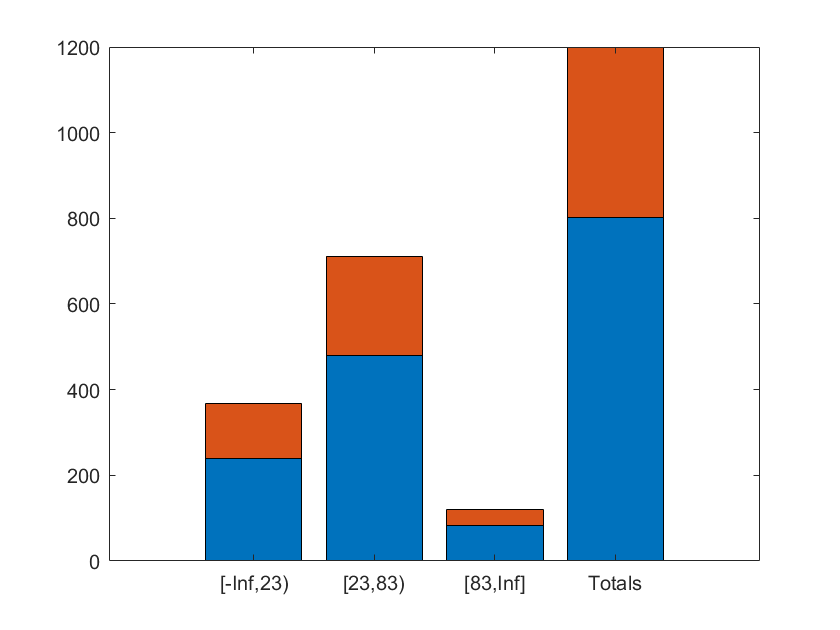


bar([bi.Good bi.Bad],'stacked');

xticklabels(bi.Bin);

## Feature Engineering

Automatically bin the scorecard data

sc_binned = autobinning( sc_binned );

## Model Fitting

Fit a logistic regression model to the WOE data. `fitmodel` internally bins the training data, transforms it into WOE values, maps the response variable so that `'Good'` is `1`, and fits a linear logistic regression model. By default, `fitmodel` uses a stepwise procedure to determine which predictors should be in the model.

[sc_binned,mdl] = fitmodel(sc_binned);

1. Adding CustIncome, Deviance = 1490.8527, Chi2Stat = 32.588614, PValue = 1.1387992e-08
2. Adding TmWBank, Deviance = 1467.1415, Chi2Stat = 23.711203, PValue = 1.1192909e-06
3. Adding AMBalance, Deviance = 1455.5715, Chi2Stat = 11.569967, PValue = 0.00067025601
4. Adding EmpStatus, Deviance = 1447.3451, Chi2Stat = 8.2264038, PValue = 0.0041285257

Generalized linear regression model:
    ResponseVar ~ [Linear formula with 5 terms in 4 predictors]
    Distribution = Binomial

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)    0.70285     0.063592    11.053    2.1313e-28
    EmpStatus      0.82998      0.29029    2.8591     0.0042482
    CustIncome     0.99058      0.18044    5.4898  

scores = probdefault(sc_binned,sc_binned.Data);

## Model Validation

The `creditscorecard` class supports three validation methods, the Cumulative Accuracy Profile (CAP), the Receiver Operating Characteristic (ROC), and the Kolmogorov-Smirnov (K-S) statistic.

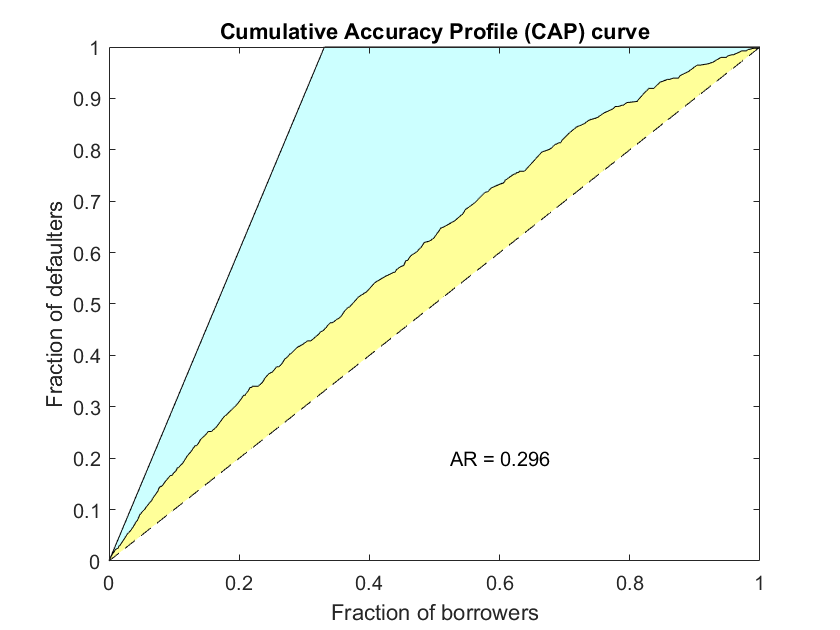

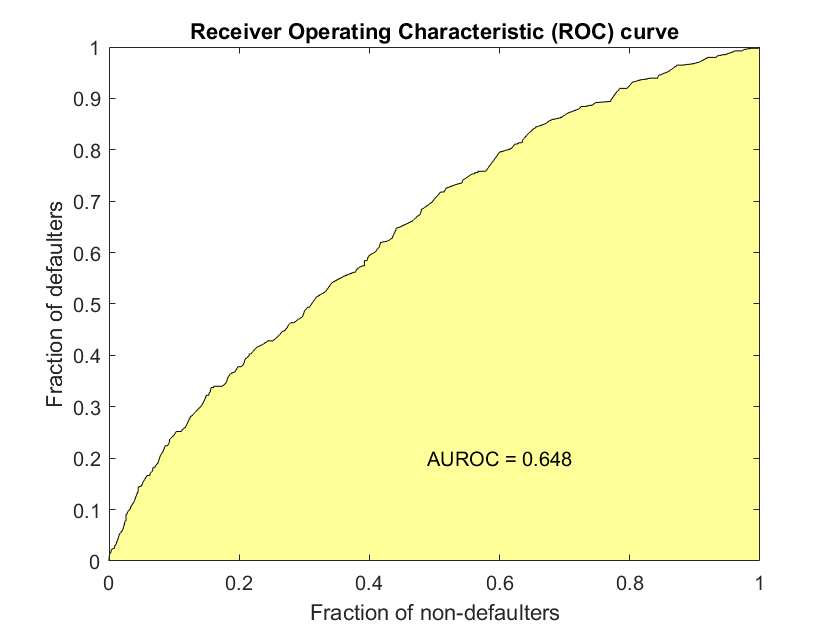

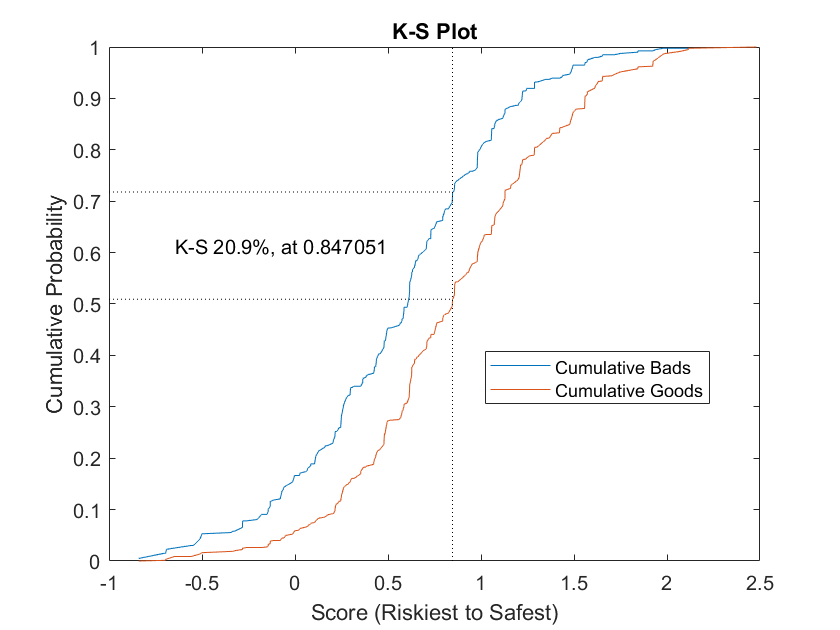

Stats = 4×2 table
            Measure              Value 
    ________________________    _______

    {'Accuracy Ratio'      }    0.29588
    {'Area under ROC curve'}    0.64794
    {'KS statistic'        }    0.20854
    {'KS score'            }    0.84705


T = 252×9 table
     Scores     ProbDefault    TrueBads    FalseBads    TrueGoods    FalseGoods    Sensitivity    FalseAlarm     PctObs  
    ________    ___________    ________    _________    _________    __________    ___________    __________    _________

    -0.84017       0.6985          2           0           803          395         0.0050378             0     0.0016667
    -0.70238      0.66872          6           1           802          391          0.015113     0.0012453     0.0058333
     -0.6951       0.6671          6           2           801          391          0.015113     0.0024907     0.0066667
    -0.69132      0.66626          9           3           800     

[Stats,T] = validatemodel(sc_binned,'Plot',{'CAP','ROC','KS'})

## Challenger Model

We compare the performance of the logistic regression fitted with the scorecard data with alternative machine learning methods. 

To do this, we extract the binned WOE values from the scorecard.

binnedFeatures = bindata( sc_binned );
predictorVars = sc_binned.PredictorVars;

**Load the Data from Refaat 2011**

Load dataset from Refaat 2011

whos -file CreditCardData

  Name             Size            Bytes  Class    Attributes

  data              -              84876  table              
  dataMissing       -              84876  table              
  dataWeights       -              94720  table              



load CreditCardData.mat

Standardize variable names

data.Properties.VariableNames{'CustID'} = 'IDVar';
data.Properties.VariableNames{'status'} = 'ResponseVar';
dataMissing.Properties.VariableNames{'CustID'} = 'IDVar';
dataMissing.Properties.VariableNames{'status'} = 'ResponseVar';
dataWeights.Properties.VariableNames{'CustID'} = 'IDVar';
dataWeights.Properties.VariableNames{'status'} = 'ResponseVar';
dataWeights.Properties.VariableNames{'RowWeights'} = 'WeightsVar';

summary(data)


Description:  Credit card dataset, from: M. Refaat, Credit Risk Scorecards, lulu.com, 2011.

Variables:

    IDVar: 1200×1 double

        Values:

            Min            1 
            Median     600.5 
            Max         1200 

    CustAge: 1200×1 double

        Values:

            Min          21    
            Median       45    
            Max          74    

    TmAtAddress: 1200×1 double

        Values:

            Min              2     
            Median          36     
            Max            207     

    ResStatus: 1200×1 categorical

        Values:

            Home Owner        542    
            Tenant            474    
            Other             184    

    EmpStatus: 1200×1 categorical

        Values:

            Employed        565    
            Unknown         635    

    CustIncome: 1200×1 double

        Values:

            Min   


summary(data)


Description:  Credit card dataset, from: M. Refaat, Credit Risk Scorecards, lulu.com, 2011.

Variables:

    IDVar: 1200×1 double

        Values:

            Min            1 
            Median     600.5 
            Max         1200 

    CustAge: 1200×1 double

        Values:

            Min          21    
            Median       45    
            Max          74    

    TmAtAddress: 1200×1 double

        Values:

            Min              2     
            Median          36     
            Max            207     

    ResStatus: 1200×1 categorical

        Values:

            Home Owner        542    
            Tenant            474    
            Other             184    

    EmpStatus: 1200×1 categorical

        Values:

            Employed        565    
            Unknown         635    

    CustIncome: 1200×1 double

        Values:

            Min   